## ESD2: Laboratory 1

Parameters:

b = 60; % baseline [mm]
f =3; % focal length [mm]
ps = .006; % focal length [mm]
xNumPix = 752; % total number of pixels in x direction of the sensor [px]
yNumPix = 480; % total number of pixels in y direction of the sensor [px]

cxLeft = xNumPix/2; % left camera x center [px]
cxRight = xNumPix/2; % right camera x center [px]

% extra param
cyLeft = yNumPix/2;
cyRight = yNumPix/2;

xLeft = 386; % What does this represent?
xRight = 366; % What does this represent?

Depth equation with a single shift:

d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)/(d * 1000); % depth [m]
disp(['The depth is: ' num2str(Z) ' [m]'])

The depth is: 1.5 [m]


Depth equation with shifts:

shift = 0:350; % Object moves from camera in Z
xLeft = cxLeft + shift;
xRight = cxRight - shift;
d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)./(d * 1000); % depth [m]
disp(['The depth is: ' num2str(Z) ' [m]'])

The depth is: Inf            15           7.5             5          3.75             3           2.5      2.142857         1.875      1.666667           1.5      1.363636          1.25      1.153846      1.071429             1        0.9375     0.8823529     0.8333333     0.7894737          0.75     0.7142857     0.6818182     0.6521739         0.625           0.6     0.5769231     0.5555556     0.5357143     0.5172414           0.5      0.483871       0.46875     0.4545455     0.4411765     0.4285714     0.4166667     0.4054054     0.3947368     0.3846154         0.375     0.3658537     0.3571429     0.3488372     0.3409091     0.3333333      0.326087     0.3191489        0.3125     0.3061224           0.3     0.2941176     0.2884615     0.2830189     0.2777778     0.2727273     0.2678571     0.2631579     0.2586207     0.2542373          0.25     0.2459016     0.2419355     0.2380952      0.234375     0.2307692     0.2272727     0.2238806     0.2205882     0.2173913     0.2142857   

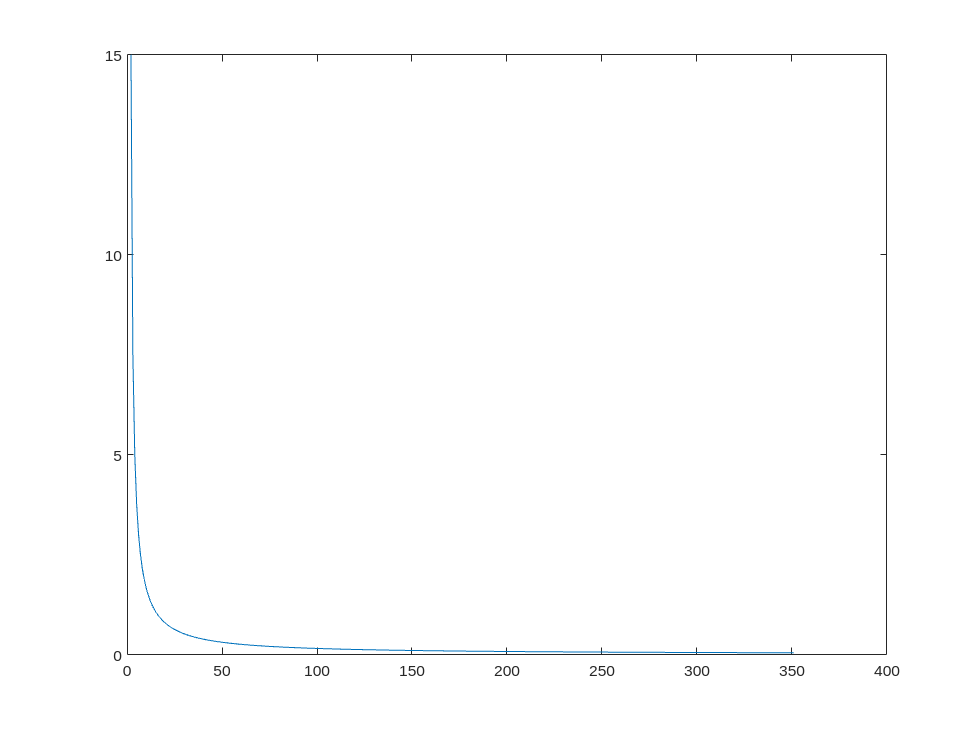

plot(Z)

Plot Depth with shifts vs Disparity:

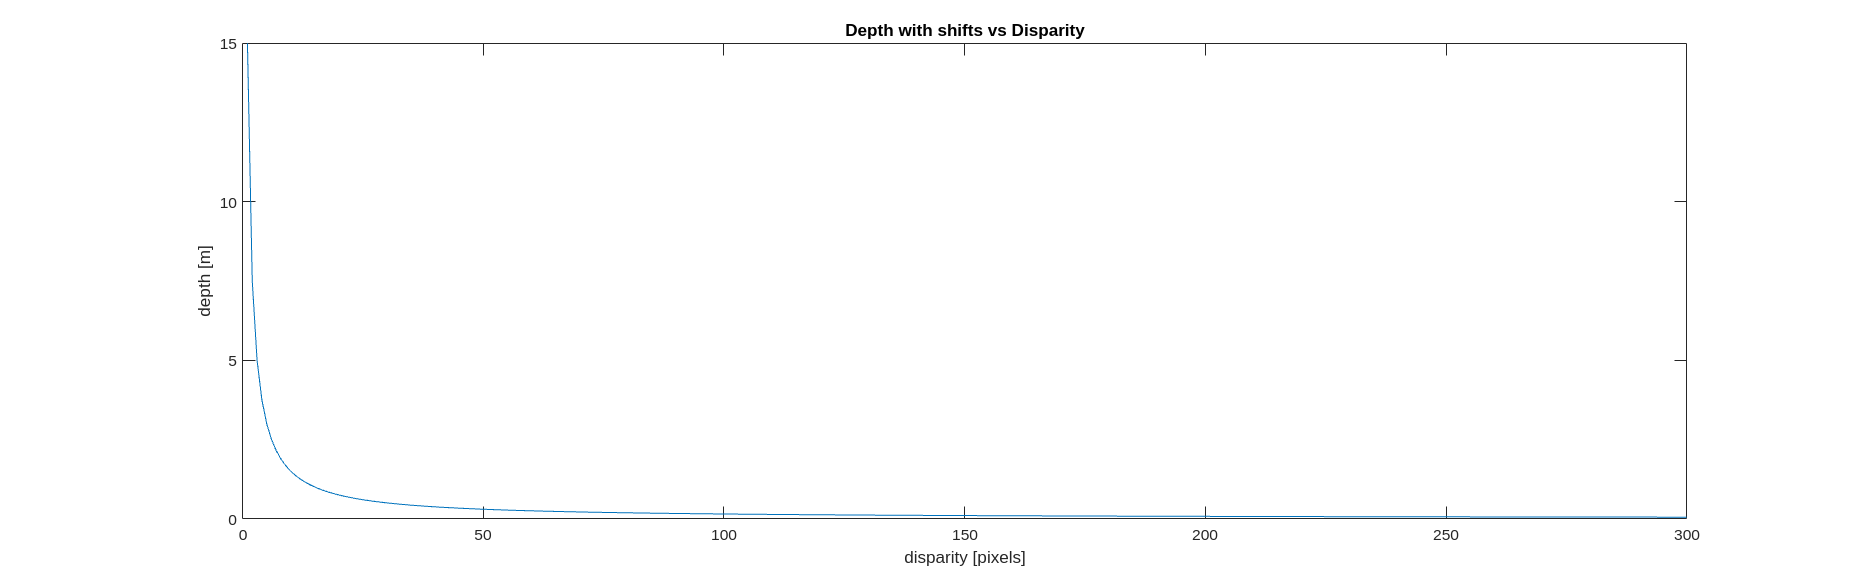

Fig = figure('Position', get(0,"ScreenSize"));
plot(shift,Z);
xlabel("disparity [pixels]");
ylabel("depth [m]");
xlim([0 300]);
title("Depth with shifts vs Disparity");
saveas(Fig, append('depth_vs_disparity.bmp'));

Subplots

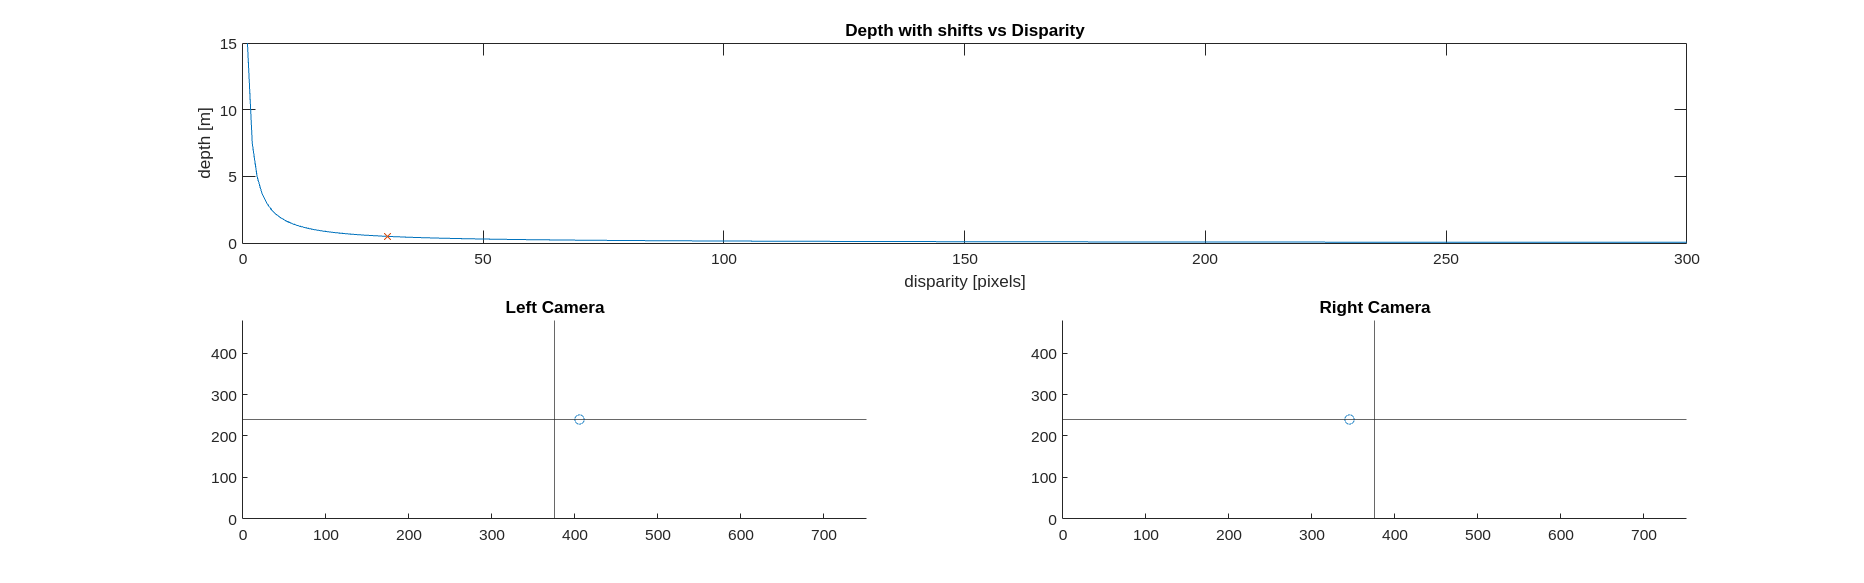

Fig = figure('Position', get(0,"ScreenSize"));
subplot(2,2,[1,2]);
plot(shift,Z);

shift = 30; % fixed pixel shift
xLeft = cxLeft + shift;
xRight = cxRight - shift;
d = (abs((xLeft-cxLeft)-(xRight-cxRight))*ps); % disparity [mm]
Z = (b * f)./(d * 1000); % depth [m]

hold on
plot(shift, Z, 'x')
xlabel("disparity [pixels]");
ylabel("depth [m]");
xlim([0 300]);
title("Depth with shifts vs Disparity");

subplot (2,2,3)
scatter(xLeft, cyLeft)
hold on
xline(cxLeft)
yline(cyLeft)
xlim([0 xNumPix])
ylim([0 yNumPix])
title('Left Camera')

subplot (2,2,4)
scatter(xRight, cyRight)
hold on
xline(cxRight)
yline(cyRight)
xlim([0 xNumPix])
ylim([0 yNumPix])
title('Right Camera')
saveas(Fig, append('depth_vs_disparity_subplots.bmp'));